# Specific: Patterns and Trends

Elaborated by Natanael Bolson

Supervised by Prof. Tad Patzek and Maxim Yutkin

EGG-ANPERC-KAUST 12/2020

Description: Identify trends and patterns 

clc
clear
close all

% Select the year from 1990 to 2015
Year_T=2015;
% Here Run the algorithm that makes the cateogrical classification
run Categorize.m

Pop=Data_EIA_H.Population(:,yo);
Pop(Clean)=[];
% to Print
P='F' % 'T' prints

P = 'F'

## Energy Rich

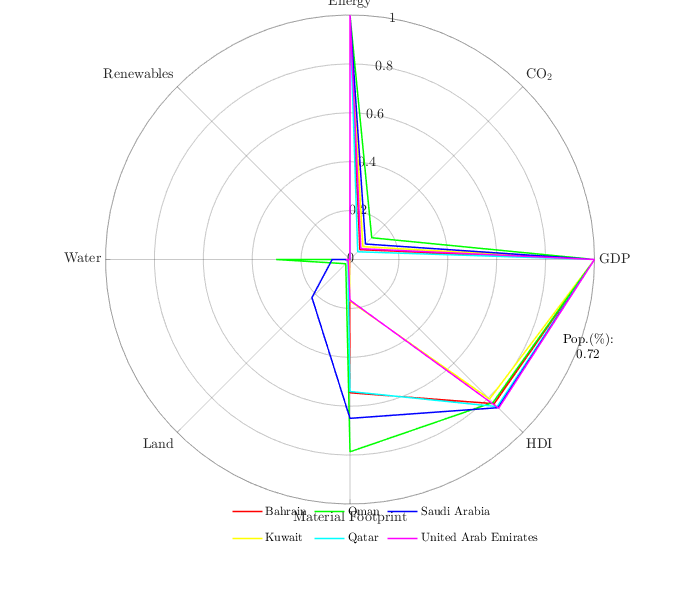

% Oil Producers 
Oil_ME=intersect(En_H,intersect(CO2_L,intersect(GDP_H,Wat_L)));
N=length(Oil_ME); 
C = hsv(N);
i=0;
figure()

for n=Oil_ME'
    i=i+1;
    Values=Ind_S(n,:);
    X=[0,45,90,135,180,225,270,315,360]*pi/180;
    Labeltheta={'GDP','$$\mathrm{CO_2}$$','Energy','Renewables','Water','Land',...
        'Material Footprint','HDI'};
    polarplot(X,Values,'Color',C(i,:),'linewidth',1.5)
    hold on
    thetaticks(0:45:315)
    thetaticklabels(Labeltheta)
    set(gca,'Fontsize',14,'TickDir','in','FontWeight','normal','GridAlpha',0.25,...
     'LineWidth',0.2,'TickLength',[0.01 0.01],'TickLabelInterpreter','latex')
    

end
LegT=Labels(Oil_ME);
ax = gca;
axPos = ax.Position;
ax.Position = axPos+ [0 0.05 0 0];
% ax='tight';
legend(LegT,'Position',[0.5 0.075 0.1 0.1],'FontSize', 12,'NumColumns',5,...
    'box','off','interpreter','latex')
set(gcf,'Position',[100 100 700 600])
Pop_OM=nansum(Pop(setdiff(Oil_ME,1)))/Pop(1)*100;
SP=sprintf('%.2f',Pop_OM);
annotation('textbox', [0.84 0.45 0 0], 'String', {'Pop.(\%):';SP}, 'FitBoxToText', true,...
    'EdgeColor','none','Interpreter',"latex",'FontSize',13,'HorizontalAlignment',"center");

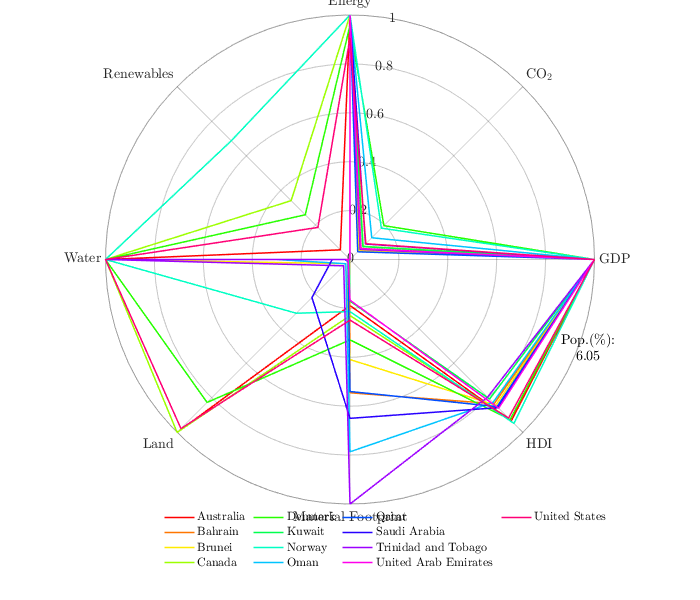

if P=='T'
    print('-depsc2','-r400','P_Oil_ME.eps')
end

Oil=intersect(En_H,intersect(CO2_L,GDP_H));
Oil=intersect(En_H,GDP_H);
N=length(Oil); 
C = hsv(N);
i=0;
figure()

for n=Oil'
    i=i+1;
    Values=Ind_S(n,:);
    X=[0,45,90,135,180,225,270,315,360]*pi/180;
    Labeltheta={'GDP','$$\mathrm{CO_2}$$','Energy','Renewables','Water','Land',...
        'Material Footprint','HDI'};
    polarplot(X,Values,'Color',C(i,:),'linewidth',1.5)
    hold on
    thetaticks(0:45:315)
    thetaticklabels(Labeltheta)
    set(gca,'Fontsize',14,'TickDir','in','FontWeight','normal','GridAlpha',0.25,...
     'LineWidth',0.2,'TickLength',[0.01 0.01],'TickLabelInterpreter','latex')
    

end
LegT=Labels(Oil);
ax = gca;
axPos = ax.Position;
ax.Position = axPos+ [0 0.05 0 0];
legend(LegT,'Position',[0.5 0.05 0.1 0.1],'FontSize', 12,'NumColumns',4,...
    'box','off','interpreter','latex')
set(gcf,'Position',[100 100 700 600])
Pop_O=nansum(Pop(setdiff(Oil,1)))/Pop(1)*100;
SP=sprintf('%.2f',Pop_O);
annotation('textbox', [0.84 0.45 0 0], 'String', {'Pop.(\%):';SP}, 'FitBoxToText', true,...
    'EdgeColor','none','Interpreter',"latex",'FontSize',14,'HorizontalAlignment',"center");

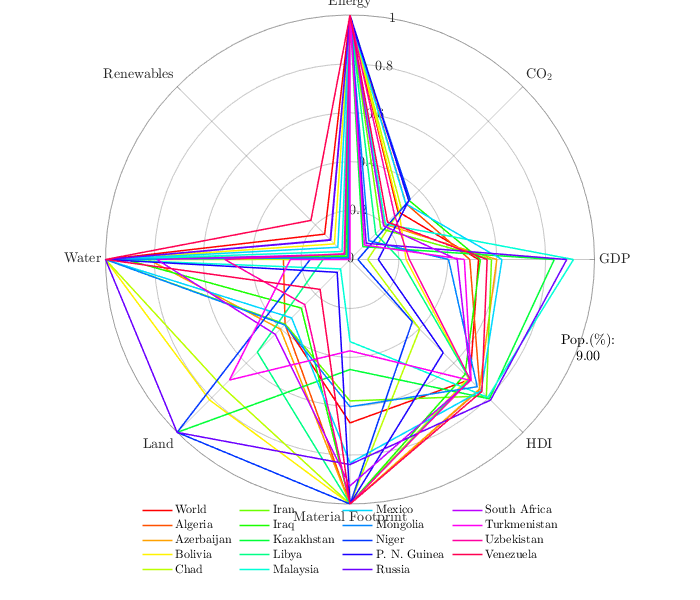

if P=='T'
    print('-depsc2','-r400','P_Oil_R.eps')
end

Oil_P=intersect(En_H,intersect(CO2_L,intersect(find(GDP_cat(:,yo)~='H'),Ren_L)));
% Oil_P=intersect(En_H,find(GDP_cat(:,yo)~='H'));
N=length(Oil_P); 
C = hsv(N);
i=0;
figure()

for n=Oil_P'
    i=i+1;
    Values=Ind_S(n,:);
    X=[0,45,90,135,180,225,270,315,360]*pi/180;
    Labeltheta={'GDP','$$\mathrm{CO_2}$$','Energy','Renewables','Water','Land',...
        'Material Footprint','HDI'};
    polarplot(X,Values,'Color',C(i,:),'linewidth',1.5)
    hold on
    thetaticks(0:45:315)
    thetaticklabels(Labeltheta)
    set(gca,'Fontsize',14,'TickDir','in','FontWeight','normal','GridAlpha',0.25,...
     'LineWidth',0.2,'TickLength',[0.01 0.01],'TickLabelInterpreter','latex')
    

end
LegT=Labels(Oil_P);
ax = gca;
axPos = ax.Position;
ax.Position = axPos+ [0 0.05 0 0];
legend(LegT,'Position',[0.45 0.05 0.1 0.1],'FontSize', 12,'NumColumns',4,...
    'box','off','interpreter','latex')
set(gcf,'Position',[100 100 700 600])
Pop_OP=nansum(Pop(setdiff(Oil_P,1)))/Pop(1)*100;
SP=sprintf('%.2f',Pop_OP);
annotation('textbox', [0.84 0.45 0 0], 'String', {'Pop.(\%):';SP}, 'FitBoxToText', true,...
    'EdgeColor','none','Interpreter',"latex",'FontSize',14,'HorizontalAlignment',"center");

if P=='T'
    print('-depsc2','-r400','P_Oil_P.eps')
end

## Poor

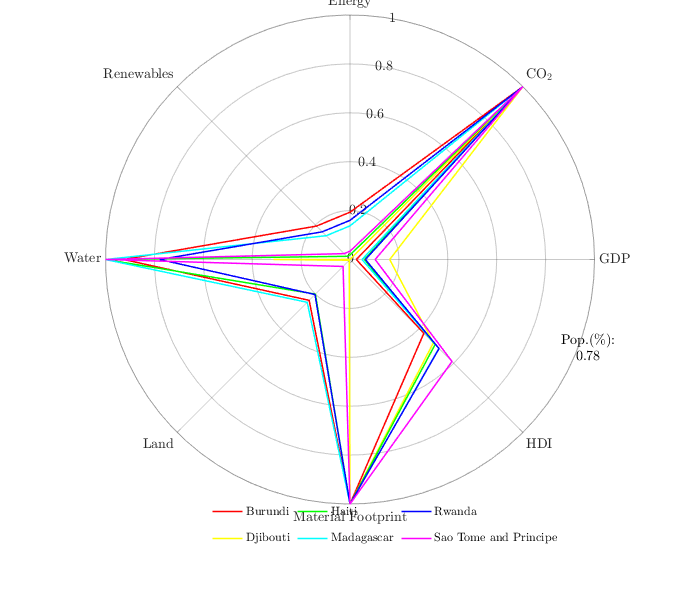

% Unsustainable
PU=intersect(Mat_H,intersect(CO2_H,Land_L));
PU=intersect(PU,intersect(En_L,Ren_L));
AP=find(Score_Y<0.25);
PU=intersect(PU,AP');
N=length(PU); 
C = hsv(N);
i=0;
figure()

for n=PU'
    i=i+1;
    Values=Ind_S(n,:);
    X=[0,45,90,135,180,225,270,315,360]*pi/180;
    Labeltheta={'GDP','$$\mathrm{CO_2}$$','Energy','Renewables','Water','Land',...
        'Material Footprint','HDI'};
    polarplot(X,Values,'Color',C(i,:),'linewidth',1.5)
    hold on
    thetaticks(0:45:315)
    thetaticklabels(Labeltheta)
    set(gca,'Fontsize',14,'TickDir','in','FontWeight','normal','GridAlpha',0.25,...
     'LineWidth',0.2,'TickLength',[0.01 0.01],'TickLabelInterpreter','latex')
    

end
LegT=Labels(PU);
ax = gca;
axPos = ax.Position;
ax.Position = axPos+ [0 0.05 0 0];
legend(LegT,'Position',[0.5 0.075 0.1 0.1],'FontSize', 12,'NumColumns',4,...
    'box','off','interpreter','latex')
set(gcf,'Position',[100 100 700 600])
Pop_PU=nansum(Pop(setdiff(PU,1)))/Pop(1)*100;
SP=sprintf('%.2f',Pop_PU);
annotation('textbox', [0.84 0.45 0 0], 'String', {'Pop.(\%):';SP}, 'FitBoxToText', true,...
    'EdgeColor','none','Interpreter',"latex",'FontSize',14,'HorizontalAlignment',"center");

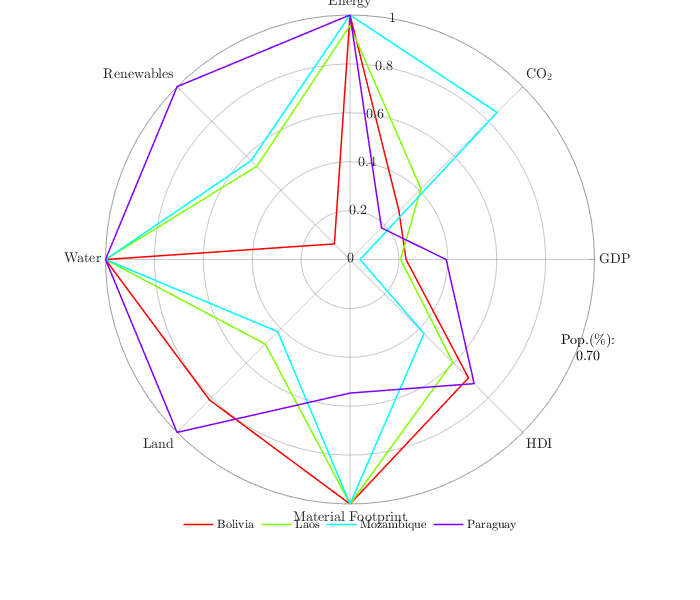

if P=='T'
    print('-depsc2','-r400','P_Poor_Uns.eps')
end

% Sustainable
PS=intersect(find(Mat_cat(:,yo)~='L'),intersect(find(GDP_cat(:,yo)=='L'),intersect(En_H,find(Land_cat(:,yo)~='L'))));
% PS=intersect(find(Mat_cat(:,yo)~='L'),intersect(En_H,find(Land_cat(:,yo)~='L')));
AP=find(Score_Y>0.35);
PS=intersect(PS,AP');
N=length(PS); 
C = hsv(N);
i=0;
figure()

for n=PS'
    i=i+1;
    Values=Ind_S(n,:);
    X=[0,45,90,135,180,225,270,315,360]*pi/180;
    Labeltheta={'GDP','$$\mathrm{CO_2}$$','Energy','Renewables','Water','Land',...
        'Material Footprint','HDI'};
    polarplot(X,Values,'Color',C(i,:),'linewidth',1.5)
    hold on
    thetaticks(0:45:315)
    thetaticklabels(Labeltheta)
    set(gca,'Fontsize',14,'TickDir','in','FontWeight','normal','GridAlpha',0.25,...
     'LineWidth',0.2,'TickLength',[0.01 0.01],'TickLabelInterpreter','latex')
    

end
LegT=Labels(PS);
ax = gca;
axPos = ax.Position;
ax.Position = axPos+ [0 0.05 0 0];
legend(LegT,'Position',[0.45 0.075 0.1 0.1],'FontSize', 12,'NumColumns',5,...
    'box','off','interpreter','latex')
set(gcf,'Position',[100 100 700 600])
Pop_PS=nansum(Pop(setdiff(PS,1)))/Pop(1)*100;
SP=sprintf('%.2f',Pop_PS);
annotation('textbox', [0.84 0.45 0 0], 'String', {'Pop.(\%):';SP}, 'FitBoxToText', true,...
    'EdgeColor','none','Interpreter',"latex",'FontSize',14,'HorizontalAlignment',"center");

if P=='T'
    print('-depsc2','-r400','P_Poor_Sus.eps')
end

## Rich

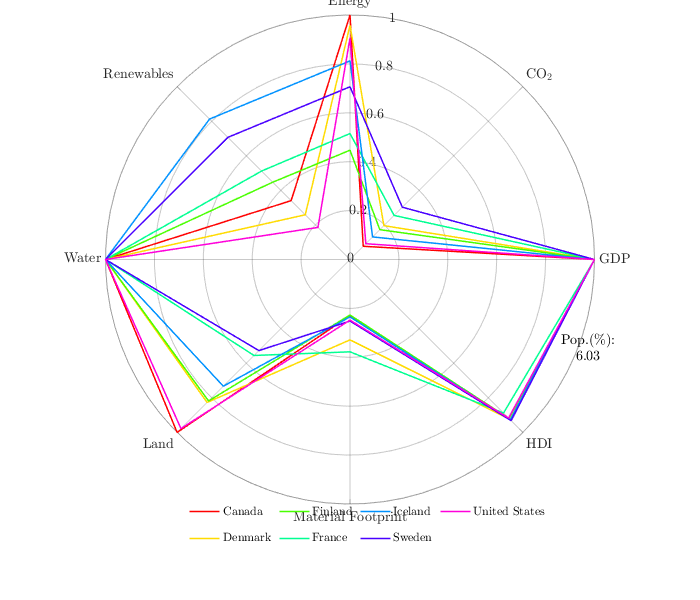

% Sustainable
RS=intersect(GDP_H,intersect(Wat_H,intersect(find(Land_cat(:,yo)~='L'),HDI_H)));
AP=find(Score_Y>0.35);
RS=intersect(RS,AP');
N=length(RS); 
C = hsv(N);
i=0;
figure()

for n=RS'
    i=i+1;
    Values=Ind_S(n,:);
    X=[0,45,90,135,180,225,270,315,360]*pi/180;
    Labeltheta={'GDP','$$\mathrm{CO_2}$$','Energy','Renewables','Water','Land',...
        'Material Footprint','HDI'};
    polarplot(X,Values,'Color',C(i,:),'linewidth',1.5)
    hold on
    thetaticks(0:45:315)
    thetaticklabels(Labeltheta)
    set(gca,'Fontsize',14,'TickDir','in','FontWeight','normal','GridAlpha',0.25,...
     'LineWidth',0.2,'TickLength',[0.01 0.01],'TickLabelInterpreter','latex')
    

end
LegT=Labels(RS);
ax = gca;
axPos = ax.Position;
ax.Position = axPos+ [0 0.05 0 0];
legend(LegT,'Position',[0.475 0.075 0.1 0.1],'FontSize', 12,'NumColumns',5,...
    'box','off','interpreter','latex')
set(gcf,'Position',[100 100 700 600])
Pop_RS=nansum(Pop(setdiff(RS,1)))/Pop(1)*100;
SP=sprintf('%.2f',Pop_RS);
annotation('textbox', [0.84 0.45 0 0], 'String', {'Pop.(\%):';SP}, 'FitBoxToText', true,...
    'EdgeColor','none','Interpreter',"latex",'FontSize',14,'HorizontalAlignment',"center");

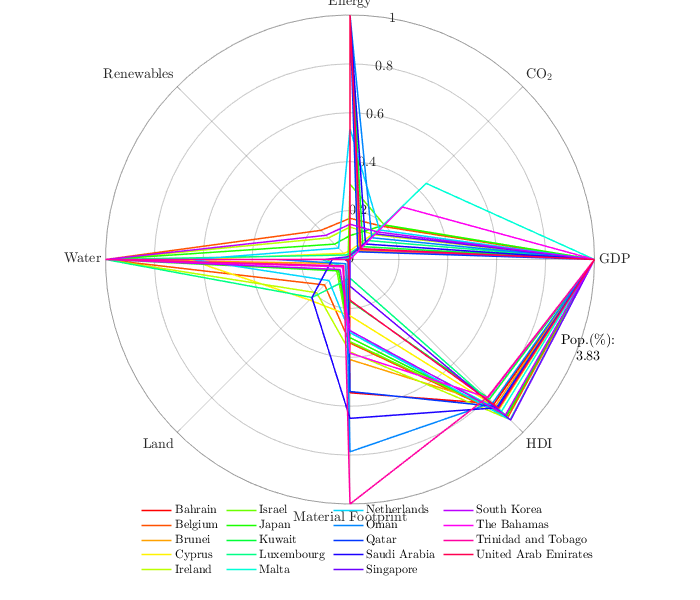

if P=='T'
    print('-depsc2','-r400','P_Rich_Sus.eps')
end

% Unsustainable
RU=intersect(find(Score_Y<0.25),GDP_H);
% AP=find(Score_Y<0.25);
% RU=intersect(RU,AP');
N=length(RU); 
C = hsv(N);
i=0;
figure()

for n=RU'
    i=i+1;
    Values=Ind_S(n,:);
    X=[0,45,90,135,180,225,270,315,360]*pi/180;
    Labeltheta={'GDP','$$\mathrm{CO_2}$$','Energy','Renewables','Water','Land',...
        'Material Footprint','HDI'};
    polarplot(X,Values,'Color',C(i,:),'linewidth',1.5)
    hold on
    thetaticks(0:45:315)
    thetaticklabels(Labeltheta)
    set(gca,'Fontsize',14,'TickDir','in','FontWeight','normal','GridAlpha',0.25,...
     'LineWidth',0.2,'TickLength',[0.01 0.01],'TickLabelInterpreter','latex')
    

end
LegT=Labels(RU);
ax = gca;
axPos = ax.Position;
ax.Position = axPos+ [0 0.05 0 0];
legend(LegT,'Position',[0.475 0.05 0.1 0.1],'FontSize', 12,'NumColumns',4,...
    'box','off','interpreter','latex')
set(gcf,'Position',[100 100 700 600])
Pop_RU=nansum(Pop(setdiff(RU,1)))/Pop(1)*100;
SP=sprintf('%.2f',Pop_RU);
annotation('textbox', [0.84 0.45 0 0], 'String', {'Pop.(\%):';SP}, 'FitBoxToText', true,...
    'EdgeColor','none','Interpreter',"latex",'FontSize',14,'HorizontalAlignment',"center");

if P=='T'
    print('-depsc2','-r400','P_Rich_Uns.eps')
end